# Notas de uso de los comandos para problemas de Linear Matrix inequalities (LMI)

En general, un problema LMI, puede definirse como:


$$N^TL(X_1.\cdots X_K)N \prec M^TR(X_1\cdots X_K)M $$


donde $X$representa un conjunto de variables matriciales con una estructura prescrita.

 $N$ y $M$ reciben el nombre de factores exteriores y L y R son los términos interiores izquierdo y derecho: **son matrices simétricas por bloques** que definen combinaciones afines entre las variables matriciales. Es muy importante fijarse en que siempre que se plantee una LMI el término de la izquierda corresponde a la parte menor de la inecuación. 

Lo vamos a ver siguiendo el ejemplo tonto de resolver una ecuación de Lyapunov para un sistema lineal.


$$\dot{x} = Ax\\
A^TP+PA \prec 0\\
P \succ 0$$


Elegimos una matriz A para nuestro sistema que sea Kurwitz y, por tanto debe cumplirse para ella la ecuación de Lyapunov


$$A = \pmatrix{
 -3 & 0 & -4 \cr 
2 & -3 & 1 \cr
0 & -1 & -3 }$$


A = [-3 0 -4; 2 -3 1; 0 -1 -3]

A =     -3     0    -4
     2    -3     1
     0    -1    -3


lambda = eig(A)

lambda =   -1.1662 + 0.0000i
  -3.9169 + 1.8767i
  -3.9169 - 1.8767i


## setlmis([])

Para definir un problema LMI lo primero que hay que hacer es activar el entorno lmis de matlab, de modo que los comandos siguientes entienda que corresponden a la definición de nuestro problema: para ello se utiliza el comando setlmis([]). Usándolo de esta forma se resetean las variables internas que matlab usa para crear LMIs y, de ese modo se puede crear un problema nuevo,

setlmis([])

## lmivar(TYPE,STRUCT)

A continuación hay que crear las variables del problema, es decir aquellos valores que debemos ajustar para que se cumpla la LMI. En nuestro ejemplo necesitamos crear exclusivamente la matriz P.  Para ello se emplea el comando lmivar(TYPE,STRUCT). La variable TYPE define la estructura de la matriz que contiene las variables de decisión (variables del problema) Puede tomar tres valores:

Matriz simétrica diagonal formada por bloques.

En este caso, TYPE =1. Es el caso típico.

Matriz completa rectangular TYPE = 2

Otro tipo de matriz TYPE = 3

La variable STRUCT completa los datos de la estructura de la matriz. Solo describo los asociados con el TYPE =1, el resto se pueden ver en el Help. La variable STRUCT es una matriz de dimensión $n\times 2$ Con una fila por cada bloque que tenga la matriz. El primer elemento de cada fila define el tamaño del bloque, por ejemplo 2, indica un bloque $2\times 2$, 3 un bloque $3\times 3$ etc.

El segundo elemento de la fila puede tomar los valores

-  (0) se trata entonces de un bloque que solo tiene elementos en la diagonal y son todos iguales $t \cdot I$. 

-  (1) un bloque diagonal completo, recordad que es simétrico.

-  (-1) un bloque de ceros.

En nuestro problema debemos definir la matriz $P$, que debe tener la misma dimensión que $A$ y ser simétrica. podemos definirla como un único bloque completo, de tamaño 3:

Por tanto lmivar(TYPE,STRUCT ) --> TYPE = 1, es una matriz simétrica (por tanto lo es por bloques). STRUCT = [3,1], nos debe definir la forma de cada bloque en nuestro caso, construimos un único bloque, por tanto STRUCT solo tiene una fila. El primer elemento representa la dimensión del bloque, en nuestro caso, el bloque tiene la dimensión de la matriz 3. Nuestro bloque (MATRIZ) debe ser simétrica así que el segúndo elemento de STRUCT le asignamos un 1. 

P = lmivar(1,[3,1])

P = 1

## lmiterm(TERMID,A,B,FLAG)

El siguiente paso es construir las inecuaciones que debemos resolver. 

Cada inecuación se construye mediante términos. la inecuación se forma automáticamente mediante la suma de los términos definidos a cada lado

de la desigualdad:

lminter + lminter ... < lminter + lminter ....

Para ello se emplea el comando lmiterm(TERMID;A;B;FLAG). Veamos cada una de sus variables.

TERMID. Es un vector de 4 entradas. la primera TERMID(1) Especifica dos cosas, el número (o etiqueta) de identificación de la inecuación a la que pertenece el término. Además si es positivo, se trata de un término de la izquierda de la inecuación, si es negativo, se trata de un término de la derecha de la inecuación.

TERMID(2:3) especifican a qué  bloque de la matriz $L$ o $R$ corresponde el término en cuestión. Como dichas matrices son simétrica por bloques, basta especificar los bloque de la diagonal y los que están por encima (debajo) de ella por ejemplo para una matriz de cuatro bloques basta especificar (1,1) (1,2) y (2,2). El cuarto valor TERMID(4) contiene la variable matricial que corresponde al término. Si se le pone un signo menos delante, se entiende que se trata de la traspuesta $-X:=X_T$.

Si lo que se pretende describir es un factor exterior estos tres valores TERMID(2:4) se ponen todos a cero. En nuestro caso, la verdad es que no usamos nunca factores exteriores.

Si el término es independiente, es decir no depende de la variable $X$, entonces se deja a cero el 4 valor de TERMID.

Las varibles A y B son matrices para contruir términos de la forma $AXB$. si no existen $A$ o $B$, se sustituyen por 1. En el caso de que lo que se esté definiendo es un factor externo entonces se incluye siempre en A, A = N y se omite B.

El flag es una variable muuuuuy útil. Si se introduce el valor 's', El término correspondiente $AXB$ pasa a expandirse como $AXB+B^TX^TA^T$, que es una expresión que uno se encuentra frecuentemente en este tipo de fiestas. Sin ir más lejos en el ejemplo que estamos resolviendo.

En nuestro ejemplo tenemos dos desigualdades:


$$A^TP+PA \prec 0\\
P \succ 0$$


La primera la podemos representar mediante:

lmiterm(TERMID,A,B,FLAG) --> TERMID = [1,1,1,P] El primer elemento es un 1 porque corresponde a la primera de nuestras dos desigualdades. El segundo y tercer elemento de la matriz, serán los dos unos, ya que nuestra inecuación tiene un único bloque, este va a ser el primer bloque de la diagonal (1,1). En nuestro caso no ha más bloques. En cuarto lugar, introducimos la matriz incógnita, que en nuestro caso es la matriz $P$ definida más arriba con lmivar. A continuación damos como varible A la matriz $A^T$En nuestro caso, no hay matriz B y, por tanto, introducimos un 1. Nos vasta emplear la etiqueta 's' para conseguir completar el termino izquierdo de nuestra primera desigualdad. Como no tiene lado derecho, no  lo definimos, de modo que ya entiende que lminterm debe ser definido negativo.

lmiterm([1,1,1,P],A',1,'s') %A'*P+P*A 

La segunda debemos representarla justo al revés; recordad que L debe ser siempre menor que R TERMID=[-2,1,1,P]. Igual que antes, ahora el primer valor de TERMID, es -2 porque estamos definiendo la segunda desigualdad y el término que describimos es el de la izquierda. Como en este caso no tenemos matriz A ni B, ponemos ambos valores a 1. Símplemente estamos exigiendo que $p$ sea definida positiva.

lmiterm([-2,1,1,P],1,1) %P

A continuación empleamos el comando LMISYS para crear una representación 'interna' (adecuada para el solver) del problema que acabamos de definir, se crea siempre así:

LMISYS = getlmis;

Y por fin estamos en condiciones de obtener una $P$ que sea una solución compatible con las restricciones creadas por nuestras desigualdades, empleando el comando feasp.

[tmin,xfeas] = feasp(LMISYS)


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                       -0.140476

 Result:  best value of t:    -0.140476
          f-radius saturation:  0.000% of R =  1.00e+09
 


tmin = -0.1405

xfeas =     0.3514
    0.1493
    0.2946
   -0.2643
   -0.1413
    0.5415


tmin, debe ser negativo para que el problema tenga solución, (podría no tenerla si las desigualdades planteadas son incompatibles con ninguna solución.

xfeas, contiene los valores de la solución, pero están en bruto, tal como los da el solver. Para obtener la forma matricial empleamos el comando dec2mat, tal como muestra la siguiente línea de código.


p = dec2mat(LMISYS,xfeas,P)

p =     0.3514    0.1493   -0.2643
    0.1493    0.2946   -0.1413
   -0.2643   -0.1413    0.5415


eig(p) %positivos

ans =     0.1447
    0.2358
    0.8070


Q = A'*p+p*A

Q =    -1.5108   -0.0427    0.0471
   -0.0427   -1.4848    0.0034
    0.0471    0.0034   -1.4174


eig(Q) %negativos

ans =    -1.5545
   -1.4629
   -1.3955


Veamos ahora un ejemplo que es continuación del problema de la estabilización de un sistema. Si el sistema es estabilizable, de be satisfacer la ecuacion de Lyapunov,


$$AP+PA^T-BB^T \prec 0$$


Creamos un sistema estabilizable por (tomado del ejemplo de estabilazabilidad),

Ai = [1 0 -2; 0 -2 0 ;2 0 3];
B = [-1 0;0 0;1 2]; 
rank(ctrb(Ai,B))

ans = 2

Construimos la matriz $BB^T$ porque matlab  no deja meter operaciones directamente en la funcion lminterm

Q = B*B'

Q =      1     0    -1
     0     0     0
    -1     0     5


Generamos un nuevo problema LMI, para evitar toda confusión con el resuelto antes, (Si no lo hacemos, y tal y como estamos trabajando, nos meterá los nuevos términos que creemos en el sistema de desigualdades que hemos definido antes

clear LMISYS
setlmis([])

$P$ debe ser de nuevo una matriz simétrica de tamaño tres, así que la difinimos como la variable como en el ejemplo anterior

P = lmivar(1,[3,1])

P = 1

Definimos los términos: los dos términos $AP+PA^T$ los definimos como en el caso anterior

lmiterm([1,1,1,P],Ai,1,'s') %A*P+P*A'

Además tenemos que añadir un término más a la izquierda, el término independiente $-BB^T$, 

lmiterm([1,1,1,0],-Q) %-Q

Planteamos los términos de la segunda desigualdad, $P \succ 0$

lmiterm([-2,1,1,P],1,1) %P

El resto es igual que antes...

LMISYS = getlmis;
[tmin,xfeas] = feasp(LMISYS)


 Solver for LMI feasibility problems L(x) < R(x)
    This solver minimizes  t  subject to  L(x) < R(x) + t*I
    The best value of t should be negative for feasibility

 Iteration   :    Best value of t so far 
 
     1                       -0.142342

 Result:  best value of t:    -0.142342
          f-radius saturation:  0.000% of R =  1.00e+09
 


tmin = -0.1423

xfeas =     0.1746
         0
    0.2881
    0.0183
         0
    0.6745


p = dec2mat(LMISYS,xfeas,P)

p =     0.1746         0    0.0183
         0    0.2881         0
    0.0183         0    0.6745


Pero ahora podemos emplear la $p$ obtenida para construir un estabilizador por realimentación de estados.

K = B'*p^-1/2

K =    -2.9494         0    0.8213
   -0.1557         0    1.4868


y podemos simular nuestro sistema de modo análogo a como hicimos en el ejemplo de estabilización.

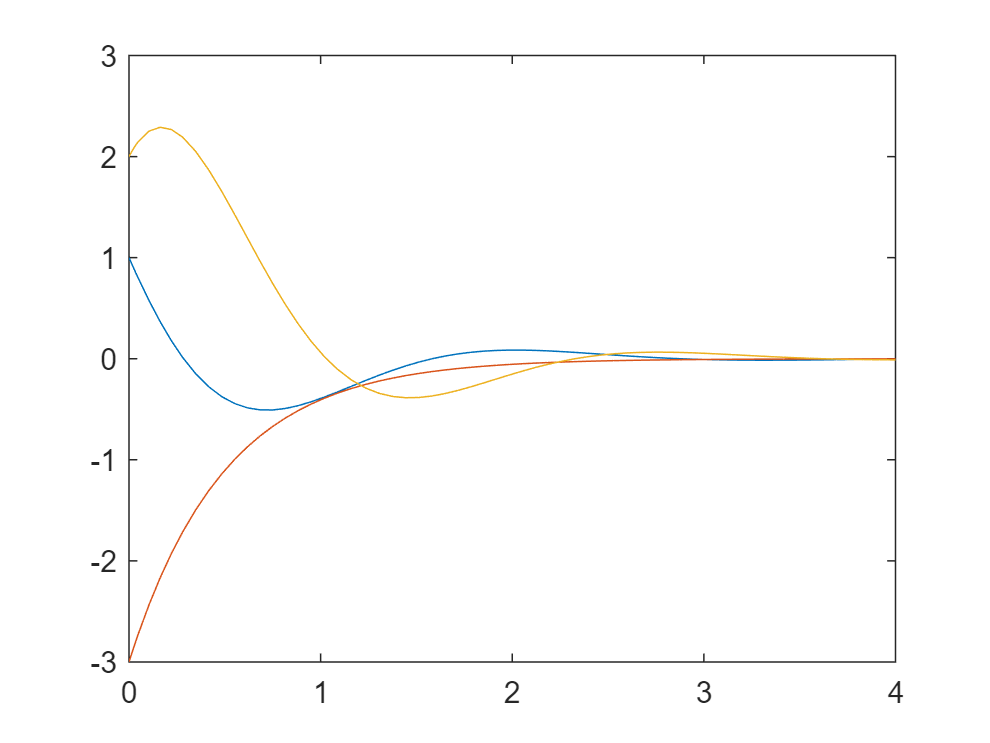

ur =@(x)U(-K,x);
sys = @(t,x)sistema_lineal(t,x,ur,Ai,B);
tf = 4;
x0 = [1;-3;2]; %elegimos una condición inicial cualquiera
%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0);%,opciones);
figure(1)
plot(t,x)

Nota final: los problemas de LMI son en sí mismo todo un campo de estudio. Para saber más, de su resolución con matlab, no queda otra que leer la documentación ;).

De todos modos, hay una función lmiedit que abra una ventana en la que se pueden definir las cosas de un modo más amigable. Pero la verdad es que no le he usado nunca...

function u = U(R,x)
    %R
u = R*x;
end


function xdot = sistema_lineal(t,x,U,A,B)
%modificamos el sistema lineal para ponerlo en modo realimentación
u = U(x);
xdot = A*x+B*u;
end